# Neurodata Without Borders Extracellular Electrophysiology Tutorial

## This tutorial

Create fake data for a hypothetical extracellular electrophysiology experiment. The types of data we will convert are:

- Voltage recording

- Local field potential (LFP)

- Spike times

It is recommended to first work through the [Introduction to MatNWB tutorial](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/intro.html), which demonstrates installing MatNWB and creating an NWB file with subject information, animal position, and trials, as well as writing and reading NWB files in MATLAB.

## Setting up the NWB File

An NWB file represents a single session of an experiment. Each file must have a session_description, identifier, and session start time. Create a new [`NWBFile`](https://neurodatawithoutborders.github.io/matnwb/doc/NwbFile.html) object with those and additional metadata. For all MatNWB functions, we use the Matlab method of entering keyword argument pairs, where arguments are entered as name followed by value.

nwb = NwbFile( ...
    'session_description', 'mouse in open exploration',...
    'identifier', 'Mouse5_Day3', ...
    'session_start_time', datetime(2018, 4, 25, 2, 30, 3, 'TimeZone', 'local'), ...
    'timestamps_reference_time', datetime(2018, 4, 25, 3, 0, 45, 'TimeZone', 'local'), ...
    'general_experimenter', 'Last Name, First Name', ... % optional
    'general_session_id', 'session_1234', ... % optional
    'general_institution', 'University of My Institution', ... % optional
    'general_related_publications', {'DOI:10.1016/j.neuron.2016.12.011'}); % optional
nwb

nwb =   NwbFile with properties:

                                             nwb_version: '2.6.0'
                                        file_create_date: []
                                              identifier: 'Mouse5_Day3'
                                     session_description: 'mouse in open exploration'
                                      session_start_time: {[2018-04-25T02:30:03.000000-04:00]}
                               timestamps_reference_time: {[2018-04-25T03:00:45.000000-04:00]}
                                             acquisition: [0×1 types.untyped.Set]
                                                analysis: [0×1 types.untyped.Set]
                                                 general: [0×1 types.untyped.Set]
                                 general_data_collection: ''
                                         general_devices: [0×1 types.untyped.Set]
                          general_expe

## Extracellular Electrophysiology

In order to store extracellular electrophysiology data, you first must create an electrodes table describing the electrodes that generated this data. Extracellular electrodes are stored in an `electrodes` table, which is also a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html). `electrodes` has several required fields: x, y, z, impedence, location, filtering, and electrode_group.

## Electrodes Table

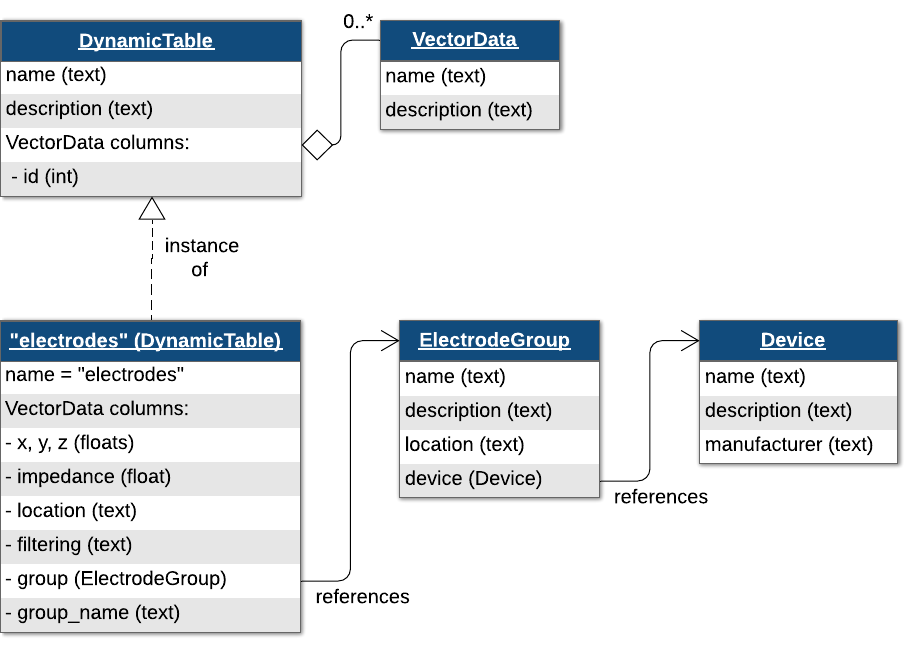

Since this is a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), we can add additional metadata fields. We will be adding a "label" column to the table.

Here, we also demonstate another method for creating `DynamicTable`s, by first creating a MATLAB native `Table` object and then calling `util.table2nwb` to convert this `Table` object into a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html).

numShanks = 4;
numChannelsPerShank = 3;

ElectrodesDynamicTable = types.hdmf_common.DynamicTable(...
    'colnames', {'location', 'group', 'group_name', 'label'}, ...
    'description', 'all electrodes');

Device = types.core.Device(...
    'description', 'the best array', ...
    'manufacturer', 'Probe Company 9000' ...
);
nwb.general_devices.set('array', Device);
for iShank = 1:numShanks
    shankGroupName = sprintf('shank%d', iShank);
    EGroup = types.core.ElectrodeGroup( ...
        'description', sprintf('electrode group for %s', shankGroupName), ...
        'location', 'brain area', ...
        'device', types.untyped.SoftLink(Device) ...
    );
    
    nwb.general_extracellular_ephys.set(shankGroupName, EGroup);
    for iElectrode = 1:numChannelsPerShank
        ElectrodesDynamicTable.addRow( ...
            'location', 'unknown', ...
            'group', types.untyped.ObjectView(EGroup), ...
            'group_name', shankGroupName, ...
            'label', sprintf('%s-electrode%d', shankGroupName, iElectrode));
    end
end
ElectrodesDynamicTable.toTable()

ans = 12×5 table
    id     location                 group                group_name            label        
    __    ___________    ____________________________    __________    _____________________

     0    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1'}    {'shank1-electrode1'}
     1    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1'}    {'shank1-electrode2'}
     2    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1'}    {'shank1-electrode3'}
     3    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2'}    {'shank2-electrode1'}
     4    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2'}    {'shank2-electrode2'}
     5    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2'}    {'shank2-electrode3'}
     6    {'unknown'}    1×1 types.untyped.ObjectView    {'shank3'} 


nwb.general_extracellular_ephys_electrodes = ElectrodesDynamicTable;

## Links

In the above loop, we create [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) objects. The `electrodes` table then uses an `ObjectView` in each row to link to the corresponding [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) object. An `ObjectView` is an object that allow you to create a link from one neurodata type referencing another. 

## ElectricalSeries

Voltage data are stored in [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects. [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) is a subclass of [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) specialized for voltage data. In order to create our [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object, we will need to reference a set of rows in the `electrodes` table to indicate which electrodes were recorded. We will do this by creating a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html), which is a type of link that allows you to reference specific rows of a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), such as the `electrodes` table, by row indices.

Create a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html) that references all rows of the `electrodes` table.

electrode_table_region = types.hdmf_common.DynamicTableRegion( ...
    'table', types.untyped.ObjectView(ElectrodesDynamicTable), ...
    'description', 'all electrodes', ...
    'data', (0:length(ElectrodesDynamicTable.id.data)-1)');

Now create an `ElectricalSeries` object to hold acquisition data collected during the experiment.

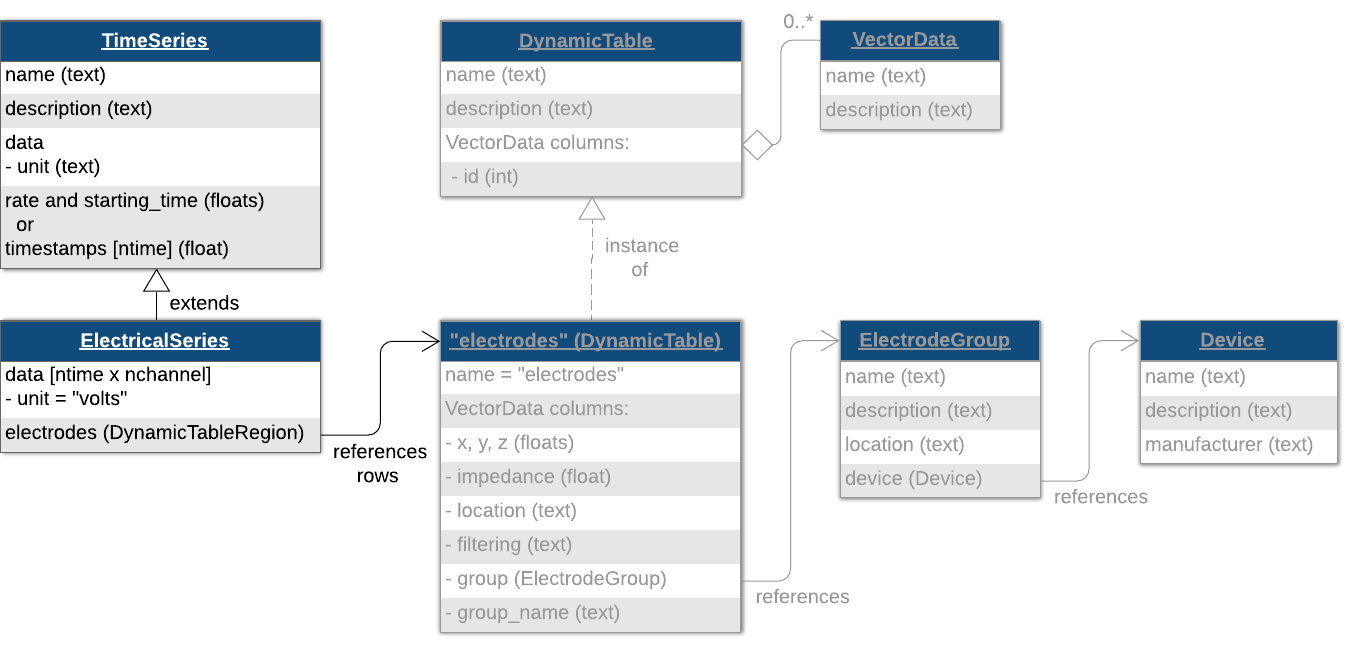

electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 30000., ... % Hz
    'data', randn(12, 3000), ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

This is the voltage data recorded directly from our electrodes, so it goes in the acquisition group. 

nwb.acquisition.set('ElectricalSeries', electrical_series);

## LFP

Local field potential (LFP) refers in this case to data that has been downsampled and/or filtered from the original acquisition data and is used to analyze signals in the lower frequency range. Filtered and downsampled LFP data would also be stored in an [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html). To help data analysis and visualization tools know that this [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object represents LFP data, store it inside an `LFP` object, then place the `LFP` object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'ecephys'`. This is analogous to how we stored the [`SpatialSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpatialSeries.html) object inside of a [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object and stored the [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'behavior'` earlier.

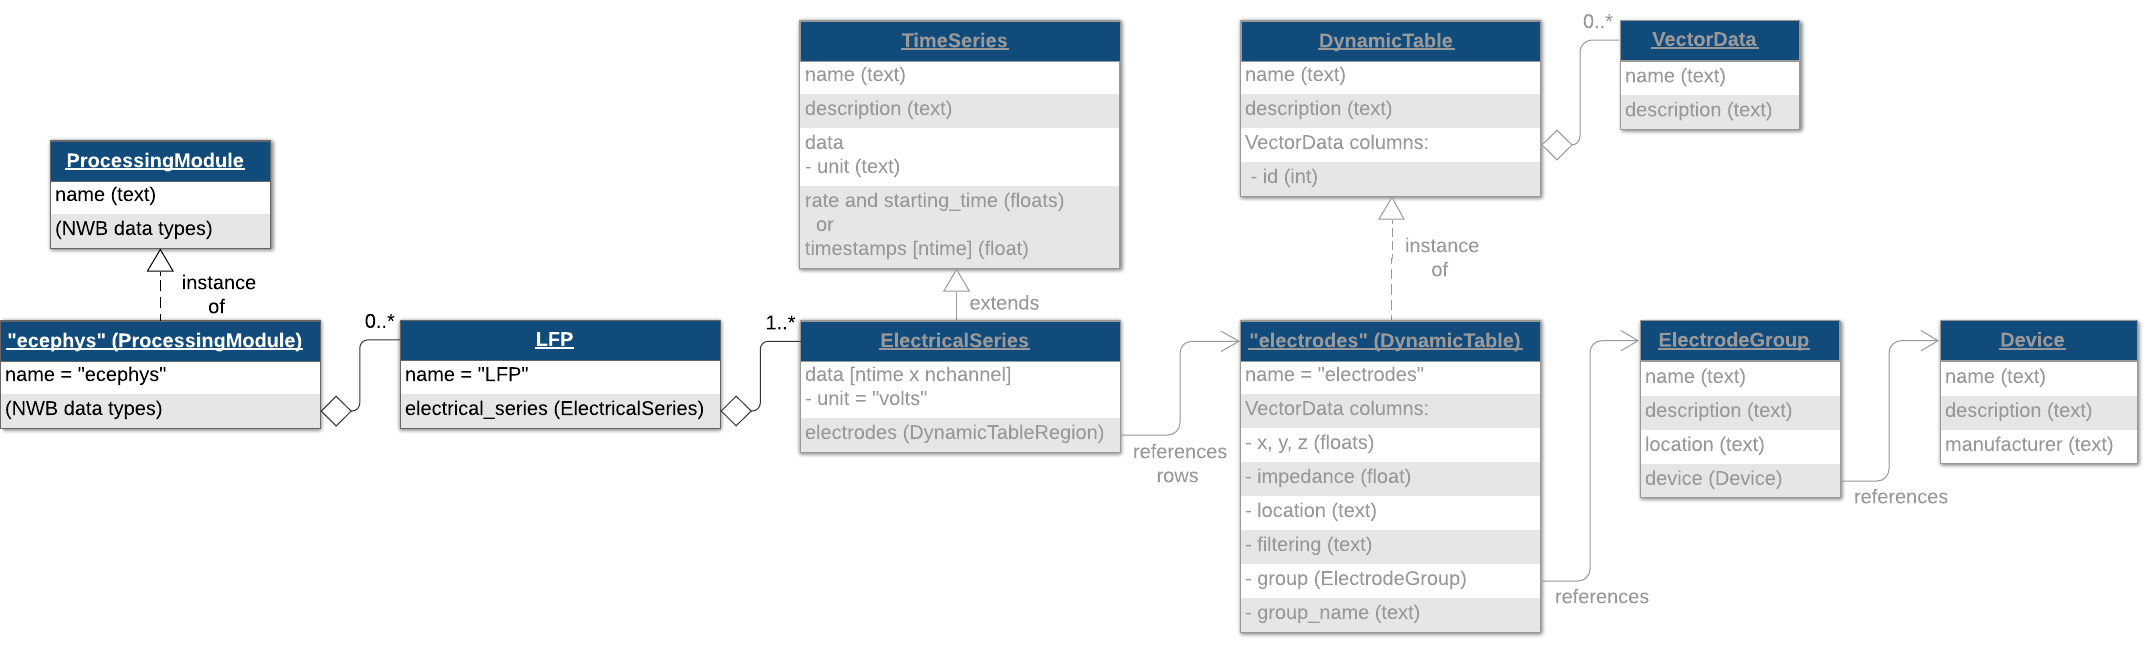

electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 1000., ... % Hz
    'data', randn(12, 100), ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

lfp = types.core.LFP('ElectricalSeries', electrical_series);

ecephys_module = types.core.ProcessingModule(...
    'description', 'extracellular electrophysiology');

ecephys_module.nwbdatainterface.set('LFP', lfp);
nwb.processing.set('ecephys', ecephys_module);

## Spike Times

#### Ragged Arrays

Spike times are stored in another [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html) of subtype [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html). The default `Units` table is at `/units` in the HDF5 file. You can add columns to the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table just like you did for `electrodes` and `trials`. Here, we generate some random spike data and populate the table. 

num_cells = 10;
firing_rate = 20;
spikes = cell(1, num_cells);
for iShank = 1:num_cells
    spikes{iShank} = rand(1, randi([16, 28]));
end
spikes

spikes = 1×10 cell array
    {[0.3740 0.7428 0.4703 0.3847 0.4485 0.1652 0.2093 0.5587 0.4400 0.3532 0.0592 0.0292 0.5391 0.7228 0.7782 0.3547 0.0692 0.0188 0.3674 0.0356 0.1224 0.9230]}    {[0.0198 0.1553 0.7804 0.8734 0.0741 0.0489 0.2423 0.5035 0.3345 0.2192 0.3156 0.5096 0.0760 0.4452 0.3416 0.2294 0.9639 0.6020 0.8869 0.4612 0.6695]}    {[0.9535 0.0468 0.2497 0.1210 0.6957 0.6096 0.4937 0.3034 0.1295 0.3859 0.4873 0.9290 0.5610 0.0303 0.7519 0.6217 0.4428 0.8836 0.9821]}    {[0.1457 0.7459 0.5717 0.5733 0.7263 0.9477 0.3135 0.5630 0.8186 0.9312 0.0239 0.6660 0.9828 0.7537 0.2354 0.9191]}    {[0.0284 0.9534 0.2276 0.2247 0.2271 0.9806 0.7608 0.3399 0.5235 0.7811 0.9805 0.0056 0.6363 0.1222 0.4550 0.1378 0.9881 0.5274 0.0664 0.5852 0.2637 0.9873 0.3417 0.9542 0.2148 0.9011]}    {[0.8309 0.5820 0.6059 0.2062 0.3717 0.6566 0.6077 0.4738 0.5806 0.5487 0.9530 0.3179 0.7639 0.9332 0.5188 0.4031]}    {[0.0803 0.8478 0.3010 0.7582 0.3781 0.9344 0.6618 0.5370 0.4941 0.7804 0.1962 0.2946 0.6

Spike times are an example of a ragged array- it's like a matrix, but each row has a different number of elements. We can represent this type of data as an indexed column of the units [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html). These indexed columns have two components, the vector data object that holds the data and the vector index object that holds the indices in the vector that indicate the row breaks. You can use the convenience function `util.create_indexed_column` to create these objects.

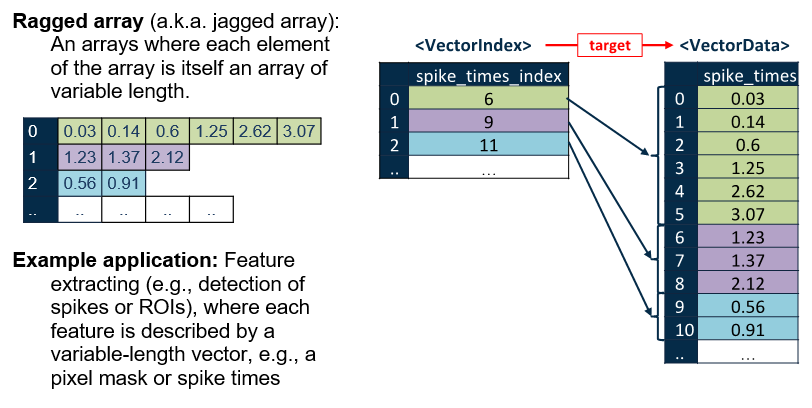

[spike_times_vector, spike_times_index] = util.create_indexed_column(spikes);

nwb.units = types.core.Units( ...
    'colnames', {'spike_times'}, ...
    'description', 'units table', ...
    'spike_times', spike_times_vector, ...
    'spike_times_index', spike_times_index ...
);

## Designating Electrophysiology Data

As mentioned above, [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects are meant for storing specific types of extracellular recordings. In addition to this [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) class, NWB provides some [Processing Modules](https://pynwb.readthedocs.io/en/stable/tutorials/general/plot_file.html#modules-overview) for designating the type of data you are storing. We will briefly discuss them here, and refer the reader to the [**API documentation**](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) and [**Intro to NWB**](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/intro.html) for more details on using these objects.

For storing spike data, there are two options. Which one you choose depends on what data you have available. If you need to store complete and/or continuous raw voltage traces, you should store the traces with [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects as acquisition data, and use the [`EventDetection`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/EventDetection.html) class for identifying the spike events in your raw traces. If you do not want to store the raw voltage traces and only the waveform ‘snippets’ surrounding spike events, you should use the [`EventWaveform`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/EventWaveform.html) class, which can store one or more [`SpikeEventSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpikeEventSeries.html) objects.

The results of spike sorting (or clustering) should be stored in the top-level [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table. Note that it is not required to store spike waveforms in order to store spike events or mean waveforms–if you only want to store the spike times of clustered units you can use only the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table.

For local field potential data, there are two options. Again, which one you choose depends on what data you have available. With both options, you should store your traces with [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects. If you are storing unfiltered local field potential data, you should store the [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects in [`LFP`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/LFP.html) data interface object(s). If you have filtered LFP data, you should store the [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects in [`FilteredEphys`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/FilteredEphys.html) data interface object(s).

## Writing the NWB File

nwbExport(nwb, 'ecephys_tutorial.nwb')

## Reading NWB Data

Data arrays are read passively from the file. Calling `TimeSeries.data` does not read the data values, but presents an HDF5 object that can be indexed to read data. This allows you to conveniently work with datasets that are too large to fit in RAM all at once. `load` with no input arguments reads the entire dataset:

nwb2 = nwbRead('ecephys_tutorial.nwb', 'ignorecache');
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data.load;

## Accessing Data Regions

If all you need is a data region, you can index a `DataStub` object like you would any normal array in MATLAB, as shown below. When indexing the dataset this way, only the selected region is read from disk into RAM. This allows you to handle very large datasets that would not fit entirely into RAM.

% read section of LFP
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data(1:5, 1:10)

ans =    -0.2598   -0.2503   -0.7306   -1.4552   -0.3254   -0.8368   -0.6304   -0.3502   -2.3128    0.0892
   -0.6888    0.1147    0.7930   -0.8179   -1.0429   -0.7021   -1.0593    0.3750    0.5636    0.1012
   -1.5281   -1.1489   -1.2679    1.5675    0.0814   -1.3598    0.8827    1.5249   -1.6651    0.2384
    0.3405    0.1056    0.1532    0.1086    1.4486    0.0502   -1.4344    0.1349    1.0144    1.4378
   -0.6437   -1.2244    0.1417   -0.8462    0.2846   -0.0092   -0.2735   -1.0856    0.4303    0.8605



% You can use the getRow method of the table to load spike times of a specific unit.
% To get the values, unpack from the returned table.
nwb.units.getRow(1).spike_times{1}

ans =     0.3740
    0.7428
    0.4703
    0.3847
    0.4485
    0.1652
    0.2093
    0.5587
    0.4400
    0.3532


# Learn more!

### See the [API documentation](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) to learn what data types are available.

## MATLAB tutorials

- [Optical physiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ophys.html)

- [Intracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/icephys.html)

## Python tutorials

See our tutorials for more details about your data type:

- [Calcium imaging](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ophys.html#sphx-glr-tutorials-domain-ophys-py)

- [Extracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ecephys.html#sphx-glr-tutorials-domain-ecephys-py)

- [Intracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/icephys.html#sphx-glr-tutorials-domain-icephys-py)

**Check out other tutorials that teach advanced NWB topics:**

- [Iterative data write](https://pynwb.readthedocs.io/en/stable/tutorials/general/iterative_write.html#sphx-glr-tutorials-general-iterative-write-py)

- [Extensions](https://pynwb.readthedocs.io/en/stable/tutorials/general/extensions.html#sphx-glr-tutorials-general-extensions-py)

- [Advanced HDF5 I/O](https://pynwb.readthedocs.io/en/stable/tutorials/general/advanced_hdf5_io.html#sphx-glr-tutorials-general-advanced-hdf5-io-py)